% model-free RL with discrete action space - make sure to set the agent in
% the RL Agent block to agentModelFreeDQN

%% PENDULUM PARAMETERS %%
init_angle=180   % Initial angle from vertical (degrees)

init_angle = 180

n_links=7       % Number of links 

n_links = 7


L=60;           % Total length of pendulum (cm)
W=2;            % Width of links (cm)
H=2;            % Depth of links (cm)
damping=0.01;     % Damping factor at joints (N*m/(deg/s))

spring=0.01;    % Torsional spring constant (N*m/deg)

base_damping= 0.5; 
max_torque =  25;
number_of_torque_steps = 12;

%% MEASUREMENT PARAMETERS %%
coord_noise_std=0;
angle_noise_std=0;

Ts = 0.1;
Tf = 100;
dt = Ts;
Taverage = 0.9;


% Setting up environment

open_system("pendulum_system_RL_model_free")

% Resetting model to default
for i=1:19
    set_param(sprintf('pendulum_system_RL_model_free/pendulum_links/pendulum_link_%d',i),'commented','off');
end

% Initialising number of links
for i=1:(20-n_links)
    set_param(sprintf('pendulum_system_RL_model_free/pendulum_links/pendulum_link_%d',i),'commented','through');
end

obsInfo = rlNumericSpec([10 1])

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [10 1]
       DataType: "double"


obsInfo.Name = "Robot States";
obsInfo.Description = "sin_phi, cos_phi, sin_theta, cos_theta, ex, ez, dphi, dx, dz, dtheta";

actInfo = rlFiniteSetSpec(1);
actInfo.Name = "Motor Torque";
actInfo.Elements = linspace(-max_torque,max_torque,number_of_torque_steps)

actInfo =   rlFiniteSetSpec with properties:

       Elements: [-25 -20.4545 -15.9091 -11.3636 -6.8182 -2.2727 2.2727 6.8182 11.3636 15.9091 20.4545 25]
           Name: "Motor Torque"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"



envModelFree = rlSimulinkEnv("pendulum_system_RL_model_free", ...
    "pendulum_system_RL_model_free/RL Agent", ...
    obsInfo,actInfo);

% NEED TO CREATE A RESET FUNCTION TO RANDOMLY INITIALISE THE STARTING ANGLE
% OF THE PENDULUM

envModelFree.ResetFcn = @(in)localResetFcn(in);
rng(0)

% Checking environment
getObservationInfo(envModelFree)

ans =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "Robot States"
    Description: "sin_phi, cos_phi, sin_theta, cos_theta, ex, ez, dphi, dx, dz, dtheta"
      Dimension: [10 1]
       DataType: "double"


getActionInfo(envModelFree)

ans =   rlFiniteSetSpec with properties:

       Elements: [-25 -20.4545 -15.9091 -11.3636 -6.8182 -2.2727 2.2727 6.8182 11.3636 15.9091 20.4545 25]
           Name: "Motor Torque"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


% Setting up network (DQN)
modelFreeNet = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(24)
    reluLayer
    fullyConnectedLayer(length(actInfo.Elements))];

modelFreeNet = dlnetwork(modelFreeNet);
summary(modelFreeNet)

   Initialized: true

   Number of learnables: 564

   Inputs:
      1   'input'   10 features



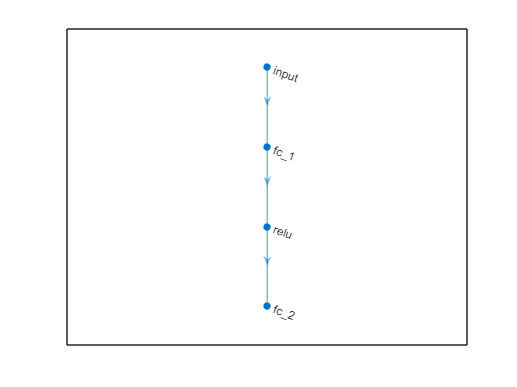

% Displaying network
figure
plot(modelFreeNet)

% Creating the agent

critic = rlVectorQValueFunction(modelFreeNet,obsInfo,actInfo);
getValue(critic,{rand(obsInfo.Dimension)})

ans = 12×1 single column vector
   -0.3110
    0.1835
   -0.0870
   -0.0969
    0.2436
    0.3515
    0.1699
   -0.0092
   -0.4032
   -0.2872


agentModelFreeDQN = rlDQNAgent(critic);
agentModelFreeDQN.AgentOptions.SampleTime = Ts;
getAction(agentModelFreeDQN,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[6.8182]}


% NEED TO ADD COMMAND TO SET AGENT AS RL BLOCK AGENT


% Training agent

%simIn = Simulink.SimulationInput('pendulum_system_RL_model_free');
%simIn = simIn.setModelParameter('FixedStep', '0.00001');

agentModelFreeDQN.AgentOptions.UseDoubleDQN = true;
agentModelFreeDQN.AgentOptions.TargetSmoothFactor = 1;
agentModelFreeDQN.AgentOptions.TargetUpdateFrequency = 4;
agentModelFreeDQN.AgentOptions.ExperienceBufferLength = 1e5;
agentModelFreeDQN.AgentOptions.MiniBatchSize = 256;
agentModelFreeDQN.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-3;
agentModelFreeDQN.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agentModelFreeDQN.AgentOptions.EpsilonGreedyExploration.Epsilon = 1;
%agentModelFreeDQN.AgentOptions.EpsilonGreedyExploration.EpsilonMin = 1;
agentModelFreeDQN.AgentOptions.EpsilonGreedyExploration.EpsilonDecay = 0.001;

global episode_number;
episode_number = 0;

trainOpts = rlTrainingOptions(...
    MaxEpisodes=5000, ...
    MaxStepsPerEpisode=Tf/Ts, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=120); 

trainingStats = train(agentModelFreeDQN,envModelFree,trainOpts);

% Simulate environment

simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts),StopOnError="off");
experiences = sim(envModelFree,agentModelFreeDQN,simOpts);
%experiences = sim(envModelFree,rlDQNAgent,simOpts);
